% Runs the M-Lyapunov function optimization for the multi-EQ
% Requires the system data generated by "run_create_limit_system.mlx"
clear;
clc;
addpath("functions\");

% Load dataset
load("limit_system.mat");
x_train = x_limit;
dx_train = dx_data;
n_train = size(x_train, 2);
n_data = size(x_data, 2);

%%% Create initial guess M-Lyapunov function
v_offset = 0.5;
% Centers for V
v_centers = zeros(2);
alphas = [-0.5; 0.5];
sig1 = 2.5; % = 1/0.4
sig2 = 3.3; % = 1/0.3
H_vec = {};
H_vec{end+1} = eye(2)*(1/sig1);
H_vec{end+1} = eye(2)*(1/sig2);
V = func_V_init(v_offset, v_centers, alphas, H_vec);

%%% Parameters for diffeomorphism phi
% Number of MPC iterations
n_iterations = 50;
% MPC horizon
n_hor = 3;
% Covariance scaling factor
sig = 1.0;
% UKF params
ukf_alpha = 1;
ukf_kappa = 1;
ukf_beta = 2;
% Initial covariances
cov_init = eye(2)*sig;
% Inverse of initial covariances
H_init = diag(1./diag(cov_init));

% Initialize diffeomorphism
phi = func_phi_init();

% Initialize alpha horizon
alpha_star = zeros(n_hor, n_train, 2);

% Initialize logging
loss_per_iter = zeros(n_iterations, 1);
vios_per_iter = zeros(n_iterations, 1);

% Normalize dynamics
dx_norm_train = dx_train ./ vecnorm(dx_train);

% Run optimization
tic;
for N=1:n_iterations

    % Get transformed covariances from UKF
    forward = @(x) func_phi_forward(x, phi);
    [~, COV_vec, H_vec] = func_ukf(forward, x_train, cov_init, ukf_alpha, ukf_kappa, ukf_beta);

    % Fit new expansion coefficients for MPC layers
    [alpha_star, z_train_H1, loss] = func_fit_lya_mpc_limit(phi, x_train, dx_norm_train, H_vec, V, alpha_star, n_hor);

    % Add first layer of MPC soluation to diffeo phi
    % Equivalent to "applying the control input from first horizon step"
    phi = func_phi_add_layer(phi, z_train_H1, squeeze(alpha_star(1, :, :)), H_vec, COV_vec);

    % Check violations on datapoints (excluding limit cycle data)
    n_vio = 0;
    dVdx_curr = func_grad_V(V, phi, x_data);
    for i=1:n_data
        L2_curr = dVdx_curr(:, i)'*dx_data(:, i);
        if L2_curr > 0
            n_vio = n_vio + 1;
        end
    end

    % Logging
    vios_per_iter(N) = n_vio;
    loss_per_iter(N) = loss;
    fprintf("ITER=%i, Vios=%i, Loss=%f \n", N, n_vio, loss);
    
end

ITER=1, Vios=4, Loss=0.408919 
ITER=2, Vios=4, Loss=0.356604 
ITER=3, Vios=4, Loss=0.228556 
ITER=4, Vios=4, Loss=0.114092 
ITER=5, Vios=2, Loss=0.049551 
ITER=6, Vios=2, Loss=0.037865 
ITER=7, Vios=2, Loss=0.034449 
ITER=8, Vios=2, Loss=0.033074 
ITER=9, Vios=2, Loss=0.032234 
ITER=10, Vios=1, Loss=0.031605 
ITER=11, Vios=1, Loss=0.028826 
ITER=12, Vios=1, Loss=0.030964 
ITER=13, Vios=0, Loss=0.029780 
ITER=14, Vios=0, Loss=0.026732 
ITER=15, Vios=0, Loss=0.028962 
ITER=16, Vios=0, Loss=0.026152 
ITER=17, Vios=0, Loss=0.027539 
ITER=18, Vios=1, Loss=0.024609 
ITER=19, Vios=0, Loss=0.026288 
ITER=20, Vios=0, Loss=0.025794 
ITER=21, Vios=0, Loss=0.025572 
ITER=22, Vios=0, Loss=0.025785 
ITER=23, Vios=0, Loss=0.025309 
ITER=24, Vios=0, Loss=0.022864 
ITER=25, Vios=0, Loss=0.024593 
ITER=26, Vios=0, Loss=0.022504 
ITER=27, Vios=0, Loss=0.023824 
ITER=28, Vios=0, Loss=0.023331 
ITER=29, Vios=0, Loss=0.023329 
ITER=30, Vios=0, Loss=0.023030 
ITER=31, Vios=0, Loss=0.023028 
ITER=32, Vios=0, 

t_opt = toc;

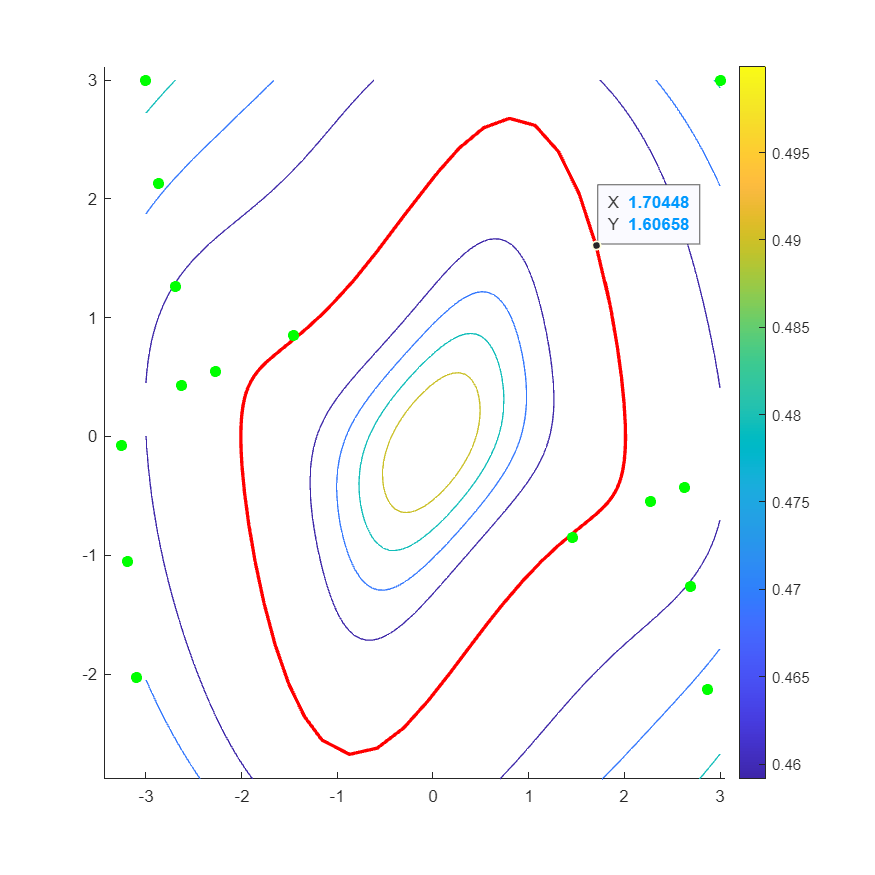

% Bounds for plotting
x1_lim = [-3, 3];
x2_lim = [-3, 3];

% Plotting and evaluation grid
n_eval_x1 = 100;
n_eval_x2 = 100;

% Create evaluation point grid
[evalgrid_x1, evalgrid_x2, x_eval] = func_grid_2D(x1_lim, x2_lim, n_eval_x1, n_eval_x2);
n_eval = size(x_eval, 2);

% Evaluate diffeo on eval grid
z_eval = func_phi_forward(x_eval, phi);

% Evaluate V on transformed evaluation points
V_fit = func_Vz(V, z_eval);
V_fit = reshape(V_fit, size(evalgrid_x1, 2), size(evalgrid_x2, 2));

% Calculate violation per datapoint
vio_per_datapoint = zeros(n_data, 1);

for i=1:size(x_data, 2)
    dVdx = func_grad_V(V, phi, x_data(:, i));
    vio_per_datapoint(i) = dx_data(:, i)'*dVdx >= 0;
end

% Plot results
figure("Position", [0 0 700 700]);
hold on;
contour(evalgrid_x1, evalgrid_x2, V_fit', linspace(0, max(V_fit(:)), 50));
plot(x_limit_full(1, :), x_limit_full(2, :), "r", "LineWidth", 2);
for i=1:n_data
    if vio_per_datapoint(i)
        plot(x_data(1, i), x_data(2, i), "r.", "LineStyle", "none", "MarkerSize", 10);
    else
        plot(x_data(1, i), x_data(2, i), "g.", "LineStyle", "none", "MarkerSize", 20);
    end
end
colorbar;

% Save result for
save("limit_results.mat", "loss_per_iter", "phi", "V", "vios_per_iter", "t_opt");